# Stationary VS Non-Stationary noise

WN, PN, and SSN are stationary noises (they are constant over time except for random variations). However, they can be rendered non-stationary by means of, e.g., amplitude- or frequency-modulation. Here, we take a look at the first one.

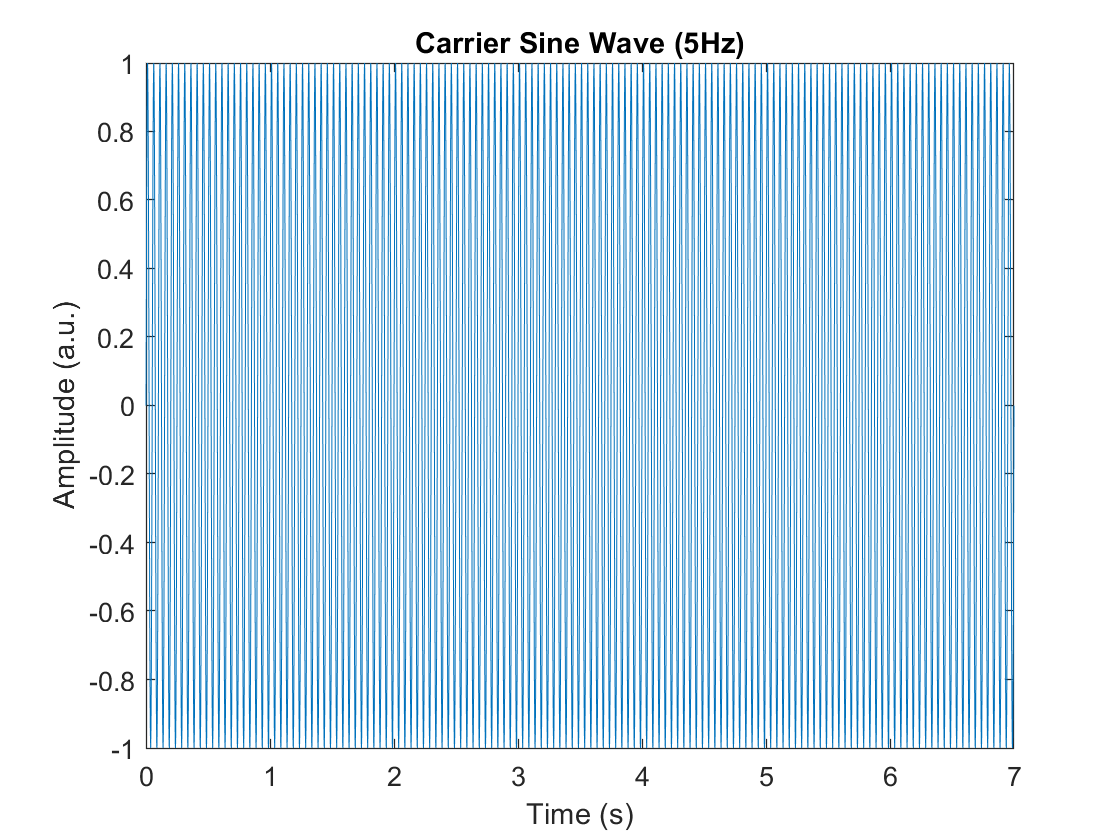

% addpath('C:\...\')

clear all; clc;

fileName = 'ENG_MA_F1_0007.wav';
BWD = which(fileName);
i = find(filesep==BWD);
BWD = BWD(1:i(end));

[S,fsS] = audioread([BWD fileName]);

brks = 0.5:7:36;
sent = cell([length(brks)-1 1]);

for i = 1:length(brks)-1
    sent{i} = S(fsS*brks(i):fsS*brks(i+1));
end

NyqFreq = fsS/2;            % fs = 2kHz; Nyquist freq. = 1 kHz
Wn = [50 5000]/NyqFreq;     % Normalised band-pass cut-off frequencies (50-5000Hz)
[b,a] = butter(6/2,Wn);     % create foreward and backward filter; 6th order            % requires the Signal Processing Toolbox
S_filt = filtfilt(b,a,S);   % use fvtool(b,a) if you want to visualise the filter

brks = 0.5:7:35.5;
sent_filt = cell([length(brks)-1 1]);

for i = 1:length(brks)-1
    sent_filt{i} = S_filt(fsS*brks(i):fsS*brks(i+1)-1);
end

clear S S_filt

whiteNoise = cell([length(brks)-1 1]);
whiteNoise_filt = cell([length(brks)-1 1]);

for i = 1:length(brks)-1
    rng('default');
    rng(i, 'Twister');
    whiteNoise{i} = randn(1, size(sent_filt{i},1));
    whiteNoise_filt{i} = filtfilt(b,a,whiteNoise{i});
end
rng('default');


Nfft            = 1000;  % FFT length
OctaveBandSpace = 1/6;   % 1/6 octave band smoothing

SSN = cell([length(brks)-1 1]);

warning('off')
for i = 1:length(brks)-1
    [spect, frqs] = Tools.LTASS...                 Compute LTASS spectrum
        (sent_filt{1}, Nfft, fsS );
    SSN{i} = Tools.ArbitraryOctaveFilt...           Speech shaped noise
        (whiteNoise_filt{1}, spect, frqs, Nfft, fsS, OctaveBandSpace);
end
warning('on')


% generate carrier
dt = 1/fsS; % seconds per sample
StopTime = 7; % seconds
tt = (0:dt:StopTime)'; % seconds
F = 20; % Sine wave frequency (hertz)
SW = sin(2*pi*F*tt);
figure; plot(tt,SW);
title('Carrier Sine Wave (5Hz)');
ylabel('Amplitude (a.u.)')
xlabel('Time (s)')

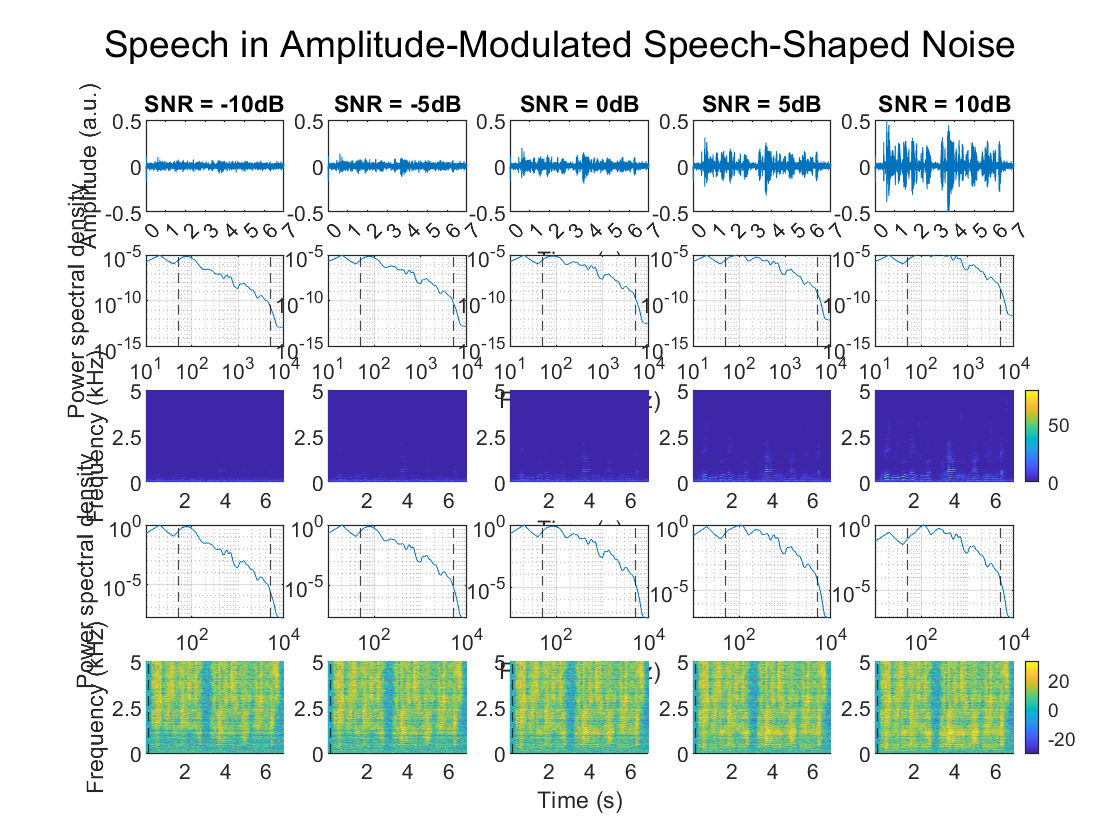


SSN_AM = cell([length(brks)-1 1]);
for i = 1:length(brks)-1
    SSN_AM{i} = conv(SSN{i}',SW(1:end-1));
    SSN_AM{i} = SSN_AM{i}(140000:end);
end



RMS_N = NaN([length(brks)-1 1]);
RMS_S = NaN([length(brks)-1 1]);
for i = 1:length(brks)-1
    RMS_N(i) = rms(SSN_AM{i});
    if i == 2
        RMS_S(i) = rms(sent_filt{i}(1:110000));
    elseif i == 3
        RMS_S(i) = rms(sent_filt{i}(1:115000));
    elseif i == 4
        RMS_S(i) = rms(sent_filt{i}(1:105000));
    elseif i == 5
        RMS_S(i) = rms(sent_filt{i}(1:100000));
    else
        RMS_S(i) = rms(sent_filt{i});
    end
end
new_RMS_N = mean(RMS_S);
ScaleFact = RMS_N./new_RMS_N;
for i = 1:length(brks)-1
    SSN_AM{i} = SSN_AM{i}./ScaleFact(i);
end

% now we add up S & N and we equalize the rms of the SiN snippets
target_dB_SNR = -10:5:10;
target_lin_SNR = 10.^(target_dB_SNR/20);

scaled_S = cell([length(brks)-1 length(target_dB_SNR)]);
SiSSN = cell([length(brks)-1 length(target_dB_SNR)]);
SiSSN_scaled = cell([length(brks)-1 length(target_dB_SNR)]);

for i = 1:length(brks)-1
    RMS_S = rms(sent_filt{i});
    actual_dB_SNR = 20*log10(RMS_S/new_RMS_N);
    actual_lin_SNR = 10^(actual_dB_SNR/20);
    for j = 1:length(target_dB_SNR)
        scaleFact_S = target_lin_SNR(j)/actual_lin_SNR;  
        scaled_S{i,j} = sent_filt{i} * scaleFact_S;
        SiSSN{i,j} = SSN_AM{i} + scaled_S{i,j};
        SiSSN_scaled{i,j} = SiSSN{i,j} ./ (rms(SiSSN{i,j})./new_RMS_N);
        % add ramps (10ms) to avoid annoying auditory glitches
        SiSSN{i,j}(1:fsS/100) = SiSSN{i,j}(1:fsS/100) .* linspace(0,1,fsS/100)';
        SiSSN{i,j}(end-fsS/100+1:end) = SiSSN{i,j}(end-fsS/100+1:end) .* linspace(1,0,fsS/100)';
        SiSSN_scaled{i,j}(1:fsS/100) = SiSSN_scaled{i,j}(1:fsS/100) .* linspace(0,1,fsS/100)';
        SiSSN_scaled{i,j}(end-fsS/100+1:end) = SiSSN_scaled{i,j}(end-fsS/100+1:end) .* linspace(1,0,fsS/100)';
    end
end



figure;
row = 1;            % waveform:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(5,5,p);
    plot(SiSSN{1,j});
    xlim([0 fsS*7]);
    xticks(0:fsS:fsS*7);
    xticklabels(0:7);
    xtickangle(45);
    ylim([-0.5 0.5]);
    title(['SNR = ' num2str(target_dB_SNR(j)) 'dB']);
    if j == 1
        ylabel('Amplitude (a.u.)');
    end
    if j == 3
        xlabel('Time (s)');
    end
end

row = 2;            % LTAS:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(5,5,p);
    if j == 1
        ltas_TH(SiSSN{1,j},fsS,'noct',6,'graph',true,'units','none','win',fsS/10,'yLim',[10^-15 10^-5],...
            'yTicks',[10^-15 10^-14 10^-13 10^-12 10^-11 10^-10 10^-9 10^-8 10^-7 10^-6 10^-5],'yL',1,...
            'xTickL',[1e1 1e2 1e3 1e4],'yTickL',[10^-15 [] [] [] [] 10^-10 [] [] [] [] 10^-5]);
    elseif j == 3
        ltas_TH(SiSSN{1,j},fsS,'noct',6,'graph',true,'units','none','win',fsS/10,'yLim',[10^-15 10^-5],...
            'yTicks',[10^-15 10^-14 10^-13 10^-12 10^-11 10^-10 10^-9 10^-8 10^-7 10^-6 10^-5],'xL',1,...
            'xTickL',[1e1 1e2 1e3 1e4],'yTickL',[10^-15 [] [] [] [] 10^-10 [] [] [] [] 10^-5]);
    else
        ltas_TH(SiSSN{1,j},fsS,'noct',6,'graph',true,'units','none','win',fsS/10,'yLim',[10^-15 10^-5],...
            'yTicks',[10^-15 10^-14 10^-13 10^-12 10^-11 10^-10 10^-9 10^-8 10^-7 10^-6 10^-5],...
            'xTickL',[1e1 1e2 1e3 1e4],'yTickL',[10^-15 [] [] [] [] 10^-10 [] [] [] [] 10^-5]);
    end
    xline(50, '--k'); xline(5000, '--k'); hold off;
end

row = 3;            % Spectrogram:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    parameter = [];
    parameter.fsAudio = fsS;
    parameter.zeroPad = fsS/10;
    [spec_SiSSN,f,t] = stft(SiSSN{1,j},parameter);

    subplot(5,5,p);
    surf(t(2:end-3),f(1:round(length(f)/2)+1),abs(spec_SiSSN(1:round(length(f)/2)+1,2:end-3)));
    hold on; set(gcf,'renderer','zbuffer');
    shading interp; view(0,90); axis tight;
    yticks([0 2500 5000]);
    yticklabels(yticks/1000);
    if j == 1
        ylabel('Frequency (kHz)')
    end
    if j == 3
        xlabel('Time (s)');
    end
    if j == 5
        colorbar;
    end
    caxis manual;
    caxis([0 80]);
end


row = 4;            % LTAS normalized:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    subplot(5,5,p);
    if j == 1
        ltas_TH(SiSSN{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'yL',1);
    elseif j == 3
        ltas_TH(SiSSN{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10,...
            'xL',1);
    else
        ltas_TH(SiSSN{1,j},fsS,'noct',6,'graph',true,'units','none','scaling','max0','win',fsS/10);
    end
    xline(50, '--k'); xline(5000, '--k'); hold off;
end


row = 5;            % Spectrogram normalized:
for j = 1:length(target_dB_SNR)
    p = row*5-5+j;
    parameter = [];
    parameter.fsAudio = fsS;
    parameter.zeroPad = fsS/10;
    spec_SiSSN = stft(SiSSN{1,j},parameter);
    
    basl_IDX = 2:3;
    baseline = mean(abs(spec_SiSSN(:,basl_IDX)),2);
    dB_pow = 10*log10(abs(spec_SiSSN)./baseline);
    
    subplot(5,5,p);
    surf(t(2:end-3),f(1:round(length(f)/2)+1),dB_pow(1:round(length(f)/2)+1,2:end-3));
    hold on; set(gcf,'renderer','zbuffer');
    shading interp; view(0,90); axis tight;
    xline(t(basl_IDX(end)), '--k');
    yticks([0 2500 5000]);
    yticklabels(yticks/1000);
    if j == 1
        ylabel('Frequency (kHz)')
    end
    if j == 3
        xlabel('Time (s)');
    end
    if j == 5
        colorbar;
    end
    caxis manual;
    caxis([-30 33]);
end

suptitle('Speech in Amplitude-Modulated Speech-Shaped Noise');